% Test plane wave propagation with the propagator

clc
clear
%close all

% units
Units


## Set up the computation

% parameters
lambda0 = 1030*nm; % center wavelength
Dlambda = 150*nm; %bandwidth

% Define the imaging system
NA = 0.15;
Mag = 60;
ftube = 160*mm;
fobj = ftube/Mag;
n = 1;

% phase plate properties
sigma_p = 0.015; %standard deviation of phase
l_phi = 15*lambda0; % correlation length

% phase plate distance to focus
dph1 = .8*mm;

% problem setup
% plot all mode
sw_plotall = 1;
plt_ctr=0;
plt_sw=0;

% testing switch
sw_test = 1;

% x-direction spatial grid
Dx = 1450*um; % length of x window
Nx = 2^11;   % number of x sample points
dx = Dx/(Nx-1); % x sample spacing
x = ([0:Nx-1]-Nx/2)*dx; % generate the x vector

% y-direction spatial grid
Dy = Dx; % length of y window
Ny = Nx;   % number of y sample points
dy = Dy/(Ny-1); % y sample spacing
y = ([0:Ny-1]-Ny/2)*dy; % generate the y vector

% spatial frequency vectors
dfx = 1/Nx/dx; % fx spacing
fx = ([0:Nx-1]-Nx/2)*dfx; % generate the fx vector
dfy = 1/Ny/dy; % fy spacing
fy = ([0:Ny-1]-Ny/2)*dfy; % generate the fy vector

% Object region spatial and spatial frequency coordinates

% make matrix versions of x and y
[X,Y] = meshgrid(x,y);

% radial coordinate
R = sqrt(X.^2+Y.^2);
rad = sqrt(x.^2 + y.^2);

% make matrix versions of fx and fy
[FX,FY] = meshgrid(fx,fy);

% radial spatial frequency coordinate
FR = sqrt(FX.^2+FY.^2);

% wavelength distribution
beta0 = 2*pi/lambda0; % center wavenumber

% compute the magic distance for Fresnel
zmagic = sqrt(((dx*Nx)^2+(dy*Ny)^2)/(1/dx^2+1/dy^2))/lambda0;

%FFT functions
myfft = @(x) fftshift(fft2(ifftshift(x)));
myifft = @(x) ifftshift(ifft2(fftshift(x)));

% propagator functions
mysqrt = @(dksq,z) real(sqrt(dksq)) + 1i*sign(z)*imag(sqrt(dksq));
angprop = @(z,lambda) exp(1i*2*pi*z*mysqrt((1/lambda)^2-(FR).^2,z));
eprop = @(e,z,lambda) myifft(myfft(e).*angprop(z,lambda));


## Set up input plane wave

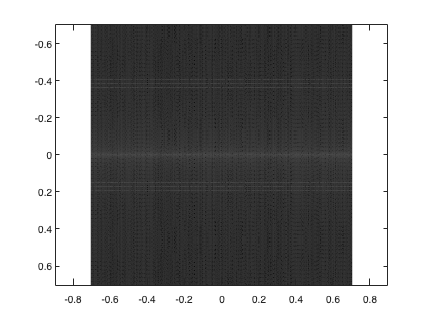

% only define and x-directed spatial frequency
thetain0 = 15/180*pi; % input angle
fxin0 = sin(thetain0)/lambda0; %input spatial frequency

% set input spatial frequency to the nearest interger multiple of the
% spatial frquency grid for the FFT
fxin = round(fxin0/dfx)*dfx; % actual input spatial frequency
thetain = asin(lambda0*fxin); % actual input angle

% Generate the input plane wave
uin = exp(1i*2*pi*fxin*X);

% look at the spectrum of the input plane wave
Uin = myfft(uin);

% plot
figure;
imagesc(fx*um,fy*um,log(abs(Uin)));
axis equal
colormap gray

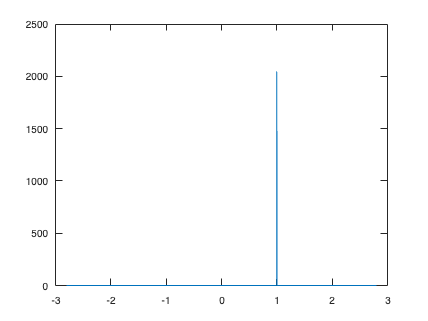


figure;plot(fx/fxin,mean(abs(Uin),1))


% the plane wave has the correct spatial frequency

% Correct ouput wave
L = 50*um;
uout = exp(1i*2*pi*fxin*X)*exp(1i*2*pi*L*cos(thetain)/lambda0);


## Use the propagator


% propagate the input field with the angular spectral propagator
uouttst = eprop(uin,L,lambda0);

kztst = 2*pi*L*mysqrt((1/lambda0)^2-(fxin).^2,L)

kztst = 294.5891


kzout=2*pi*L*cos(thetain)/lambda0

kzout = 294.5891


max(abs(uout(:)))

ans = 1.0000

max(abs(uouttst(:)))

ans = 1.0000


norm(uout,2)

ans = 2.0460e+03

norm(uouttst,2)

ans = 2.0460e+03


error = norm(uout-uouttst,2)/norm(uout,2)

error = 7.1447e-14

## Make slices

Nslice = 390; % number of slices
dL =  L/Nslice; % slice length


% initialize
udL = uin;
for ii=1:Nslice

    % propagate slice
    udL = eprop(udL,dL,lambda0);

end


% slice error
error = norm(uout-udL,2)/norm(uout,2)

error = 8.4002e-14